# **[Self] Chapter15-practice (Lec10) [ALL CORRECT]**

xtest = 6;
x1test = 1.5;
x2test = 1.5;

## **Linear**

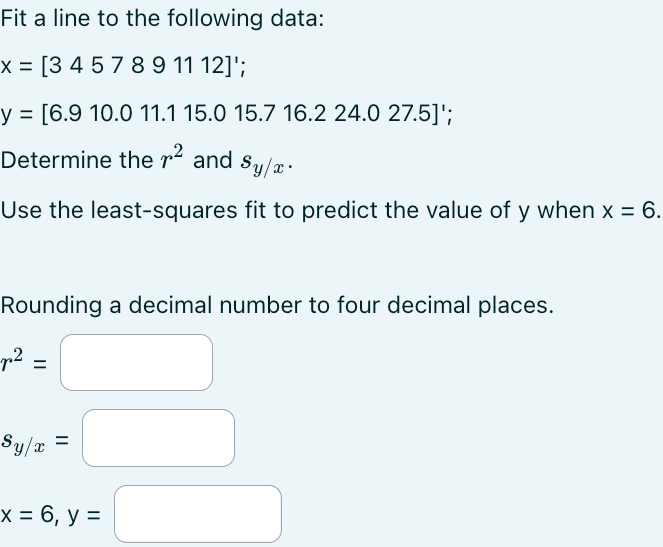

aL =     2.0900    0.3861


r2L = 0.9494

xL = [3 4 5 7 8 9 11 12]';
yL = [6.9 10.0 11.1 15.0 15.7 16.2 24.0 27.5]';
[aL, r2L] = linregr(xL, yL)

resL = yL - aL(2) - (aL(1) .* x)

resL =     0.2438
    1.2538
    0.2638
   -0.0162
   -1.4063
   -2.9963
    0.6237
    2.0337


srL = sum(resL .^ 2)

srL = 17.1814

syxL = sqrt(srL / (length(xL) - 2)) % "2" comes from "degree + 1"

syxL = 1.6922

ypredL = aL(2) + (aL(1) .* xtest) % no residuals needed

ypredL = 12.9262

## Quadratic

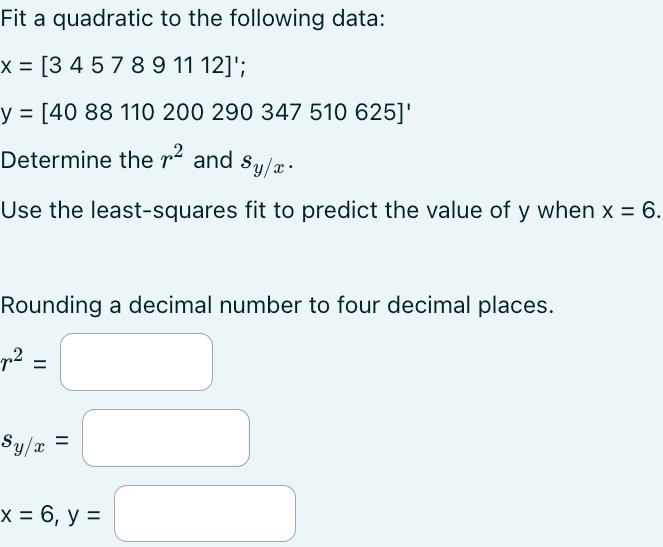

nQ = 2

nQ = 2

xQ = [3 4 5 7 8 9 11 12]';
yQ = [40 88 110 200 290 347 510 625]';
pQ = polyfit(xQ, yQ, n)

pQ =     4.4384   -3.0965   16.6925


valQ = polyval(pQ, xQ)

valQ =    47.3487
   75.3211
  112.1704
  212.4994
  275.9791
  348.3357
  519.6793
  618.6663


srQ = sum((yQ - valQ).^2)

srQ = 707.8754

stQ = sum((yQ - mean(yQ)).^2)

stQ = 3.0617e+05

r2Q = 1 - (srQ/stQ)

r2Q = 0.9977

syxQ = sqrt(srQ / (length(yQ) - (n+1)))

syxQ = 11.8985

ypredQ = polyval(pQ, xtest)

ypredQ = 157.8965

## Multiple

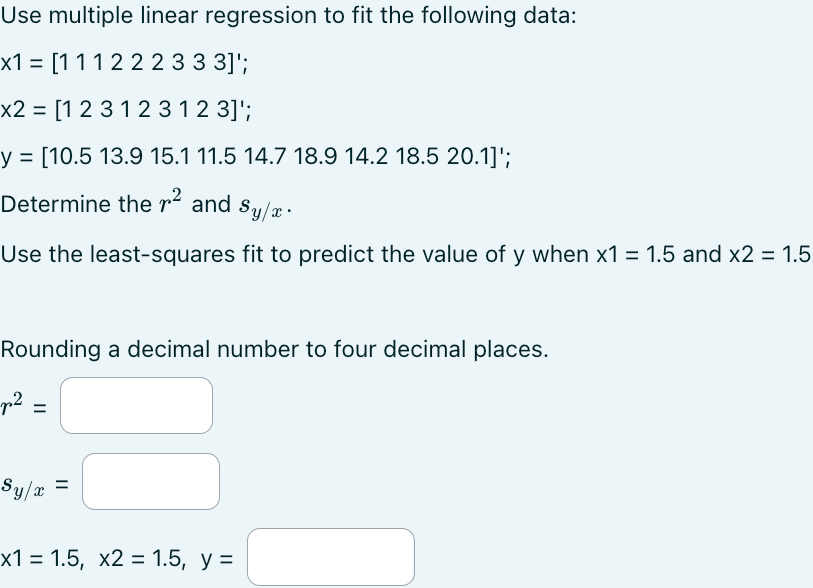

x1 = [1 1 1 2 2 2 3 3 3]';
x2 = [1 2 3 1 2 3 1 2 3]';
y = [10.5 13.9 15.1 11.5 14.7 18.9 14.2 18.5 20.1]';
Z = [ones(size(y)) x1 x2] % has ones() because we're using the default polynomial expression (not specified otherwise)

Z =      1     1     1
     1     1     2
     1     1     3
     1     2     1
     1     2     2
     1     2     3
     1     3     1
     1     3     2
     1     3     3


a = (Z' * Z) \ (Z' * y) % the coefficient vector

a =     4.8667
    2.2167
    2.9833


st = sum((y - mean(y)).^2)

st = 87.2800

sr = sum((y - Z*a).^2)

sr = 4.3967

r2 = 1 - (sr/st) % coefficient of determination

r2 = 0.9496

syx = sqrt(sr / (length(y) - length(a)))

syx = 0.8560

ypredM = a(1) + (a(2) * x1test) + (a(3) * x2test)

ypredM = 12.6667